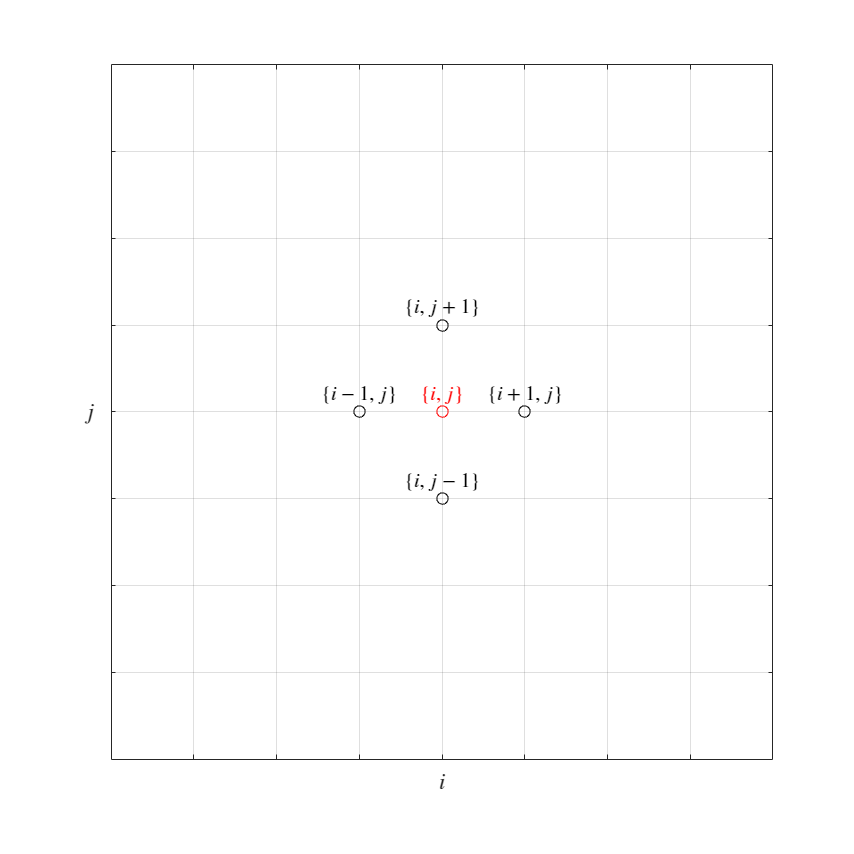

clear
clc

L = 1;
N = 8;
D = L/N;

fg = figure(Position=[0,0,600,600]);
plot(-1,-1)
xlim([0,L])
ylim([0,L])
grid on
xticks(0:D:L)
yticks(0:D:L)
xticklabels("")
yticklabels("")
xlabel("$i$","Interpreter","latex")
ylabel("$j$","Interpreter","latex",'Rotation',0)

sz = 32;

hold on
scatter((N/2)*D,(N/2)*D,sz,'r')
scatter((N/2 + 1)*D,(N/2)*D,sz,'k')
scatter((N/2 - 1)*D,(N/2)*D,sz,'k')
scatter((N/2)*D,(N/2 + 1)*D,sz,'k')
scatter((N/2)*D,(N/2 - 1)*D,sz,'k')
hold off

text((N/2)*D,(N/2)*D+L/100,"$\{i,j\}$", ...
    "Interpreter","latex", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center", "Color",'r')
text((N/2 + 1)*D,(N/2)*D+L/100,"$\{i+1,j\}$", ...
    "Interpreter","latex", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center")
text((N/2 - 1)*D,(N/2)*D+L/100,"$\{i-1,j\}$", ...
    "Interpreter","latex", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center")
text((N/2)*D,(N/2 + 1)*D+L/100,"$\{i,j+1\}$", ...
    "Interpreter","latex", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center")
text((N/2)*D,(N/2 - 1)*D+L/100,"$\{i,j-1\}$", ...
    "Interpreter","latex", ...
    "VerticalAlignment","bottom", ...
    "HorizontalAlignment","center")

saveas(fg,"Grid","svg")